clear all
clc
close all


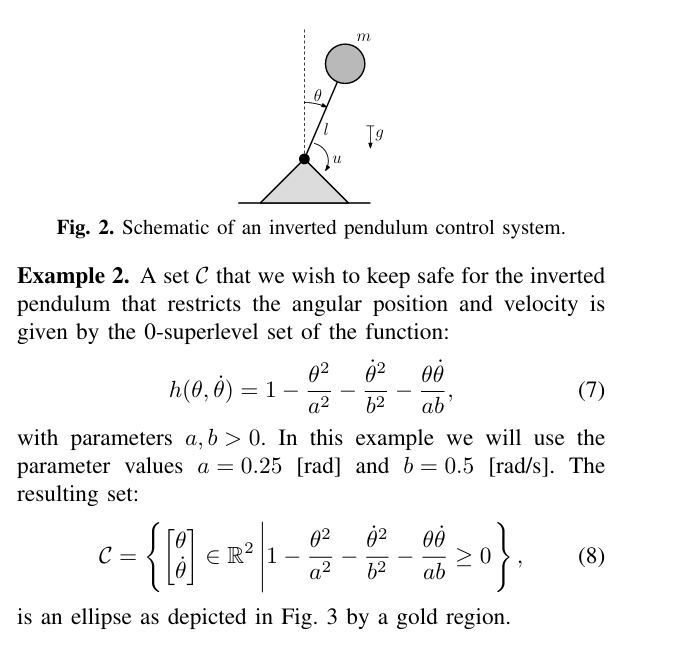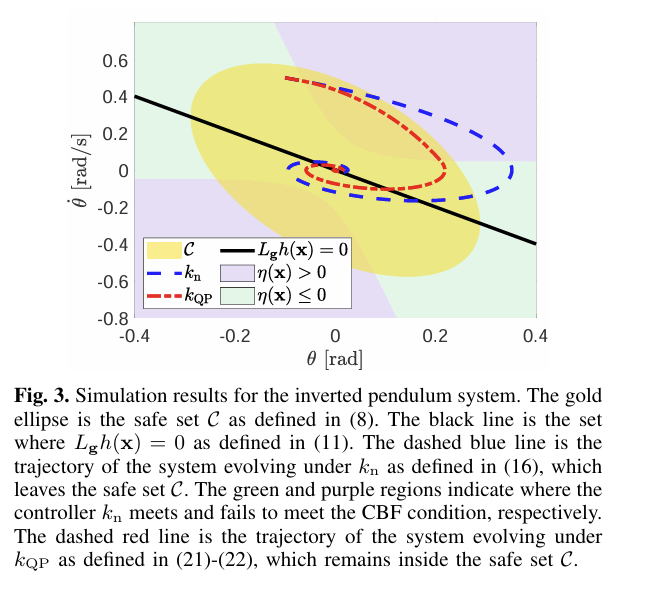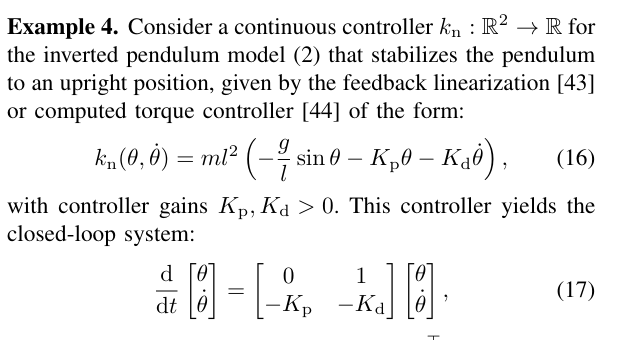

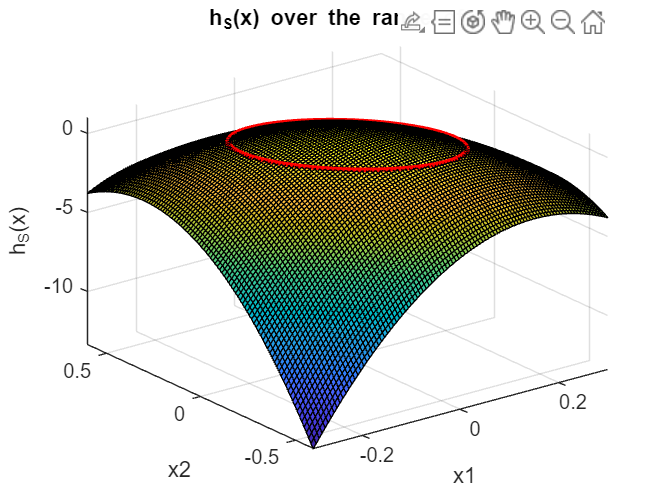

% Example parameters
a = 0.137;  % Example scalar value for a
b = 0.274;  % Example scalar value for b

% Define the range for x
x1_min = -0.3;
x1_max = 0.3;
x2_min = -0.6;
x2_max = 0.6;

% Create a grid of x values within the specified range
[x1, x2] = meshgrid(linspace(x1_min, x1_max, 100), linspace(x2_min, x2_max, 100));

% Initialize matrix to store h values
h_values = zeros(size(x1));

% Calculate h for each point in the grid
for i = 1:numel(x1)
    x = [x1(i); x2(i)];
    h_values(i) = hS_function(x, a, b);
end

% Plot the results
figure;
surf(x1, x2, h_values);
xlabel('x1');
ylabel('x2');
zlabel('h_S(x)');
title('h_S(x) over the range of x');
hold on;

% Visualize the region where h_S(x) >= 0
contour3(x1, x2, h_values, [0 0], 'LineWidth', 3, 'LineColor', 'r');
hold off;

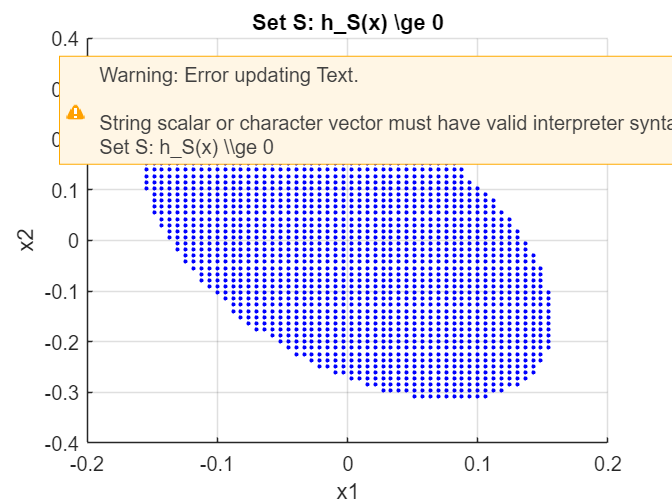


% Create a new figure for the set where h_S(x) >= 0
figure;
hold on;
xlabel('x1');
ylabel('x2');
title('Set S: h_S(x) \ge 0');

% Plot the points where h_S(x) >= 0
for i = 1:numel(x1)
    if h_values(i) >= 0
        plot(x1(i), x2(i), 'b.');
    end
end

% Add grid and axis labels
grid on;
hold off;

function hS = hS_function(x, a, b)
    % x should be a column vector
    % a and b are scalars
    
    % Construct the matrix
    A = [1/a^2, 0.5/(a*b); 0.5/(a*b), 1/b^2];
    
    % Calculate the value of the function
    hS = 1 - x' * A * x;
end